# Análisis tiempo-frecuencia de señales de radar mmWave

**Clase SlowPocket: caminata lenta con las manos en los bolsillos**

Curso: Procesamiento de Señales e Imágenes Digitales (IEE239-08M2)

Docente: Ing. Juan Miguel Urco

Integrantes: 20185876 Quintanilla Quispe, Brandon Felix · 20210670 Asencios Gomez, Leonardo William · 20210792 Vásquez Bernal, Carlos Alberto

Pontificia Universidad Católica del Perú — Facultad de Ciencias e Ingeniería — Ciclo 2026-2

Este documento continúa el análisis desarrollado para la clase `Fast` y lo aplica a la clase `SlowPocket` del dataset de Gambi et al. (2020). Es **autocontenido**: todas las funciones de procesamiento están al final, en la sección de funciones locales, así que no depende de ningún otro archivo .m.

clearvars; close all; clc;

RAIZ    = 'D:\Escritorio\ProyectoPSID';
CARPETA = fullfile(RAIZ, 'SlowPocket');
SALIDA  = fullfile(RAIZ, 'resultados', 'SlowPocket');

## 1. El dataset y el sistema de radar

Los datos provienen de:

E. Gambi, G. Ciattaglia, A. De Santis, L. Senigagliesi, "Millimeter wave radar data of people walking", *Data in Brief* **31** (2020) 105996. [https://doi.org/10.1016/j.dib.2020.105996](https://doi.org/10.1016/j.dib.2020.105996)

**Montaje.** Radar FMCW Texas Instruments **AWR1642** (77 GHz, 2 TX y 4 RX) con tarjeta de captura **DCA1000 EVM** conectada directamente a los ADC. Las muestras viajan por UDP al PC y se convierten a `.mat` con un script de MATLAB. El escenario es un pasillo de 12 m sin mobiliario. En cada ensayo el sujeto se aleja del radar hasta unos 10 m, da la vuelta y regresa. La toma dura 16 s.

**Importante:** aunque el AWR1642 es capaz de funcionar como MIMO, el dataset se tomó usando **un solo transmisor** y los cuatro receptores. Por tanto el array es un ULA de 4 elementos y no hay array virtual.

**Contenido.** La parte 1 del repositorio tiene tres clases (`Fast`, `Slow` y `SlowPocket`), cada una con 19 sujetos × 3 repeticiones = 57 ensayos. Aquí se analizan los 19 ensayos contenidos en el primero de los tres archivos comprimidos de `SlowPocket`.

**Estructura de cada archivo.** `adc_Data.mat` guarda una tabla de MATLAB de **4 columnas × 26 214 400 filas** en `complex double`. Cada fila es un instante de muestreo y cada columna la serie temporal de un receptor (`adc_DataRX1` ... `adc_DataRX4`). Esas 26,2 millones de muestras no son un flujo plano, sino:


$$26\,214\,400 = 512\ \textrm{muestras/chirp} \times 128\
 \textrm{chirps/frame} \times 400\ \textrm{frames}$$


Recuperar esa estructura con un `reshape` es el primer paso de todo el procesamiento.

## 2. Parámetros de configuración del radar

Todos los valores primarios salen de la Tabla 3 del artículo. El resto son magnitudes derivadas.

Hay un detalle fácil de pasar por alto: la **periodicidad de frame es de 40 ms**, pero el frame activo dura solo $128 \times 160\ \mu s = 20{,}48$ ms. Es decir, el radar escucha el 51,2 % del tiempo y entre frames queda un hueco de 19,52 ms sin muestras. Por eso el muestreo lento solo es uniforme **dentro** de cada frame, y no se pueden concatenar chirps de frames distintos como si fueran una secuencia continua.

P = cfg_radar();
tabla_parametros(P);

Pendiente del chirp     S      = 60.012 MHz/us
Ancho de banda          B      = 3.60 GHz (muestreado 3.073 GHz)
Muestreo del ADC        Fs     = 10 Msps, 512 muestras/chirp
Tiempo de chirp         Tchirp = 160 us (idle 100 + rampa 60)
Repetición lenta        PRF    = 6250 chirps/s
Frame                          = 128 chirps = 20.48 ms activos
Periodicidad de frame          = 40 ms -> 25 frames/s, 51.2 % de ciclo útil
Adquisición                    = 400 frames = 16 s = 26214400 muestras/RX
Resolución de rango     dR     = 4.88 cm, Rmax = 12.49 m
Resolución de velocidad dv     = 0.095 m/s, vmax = +/- 6.08 m/s
Longitud de onda        lambda = 3.89 mm
Array 1 TX x 4 RX -> 4 elementos, resolución angular ~28.6 grados


## 3. Inventario de las adquisiciones y control de duplicados

Se recorre la carpeta buscando archivos `adc_Data.mat`. La búsqueda es recursiva, así que funciona sin importar cómo quede el árbol al descomprimir.

T = localizar_adquisiciones(CARPETA);
fprintf('Adquisiciones encontradas: %d  (%.2f GB en total)\n', height(T), sum(T.GB));

Adquisiciones encontradas: 19  (7.74 GB en total)


disp(head(T(:,{'Clase','Ensayo','GB'}), 5));

       Clase        Ensayo      GB   
    ____________    ______    _______

    "SlowPocket"     "1"      0.40722
    "SlowPocket"     "2"       0.4054
    "SlowPocket"     "3"      0.40604
    "SlowPocket"     "4"      0.40908
    "SlowPocket"     "5"      0.40907



El dataset publicado contiene un **ensayo duplicado**. Los archivos de los ensayos 16 y 17 tienen exactamente el mismo tamaño y difieren en solo 3 bytes, todos dentro de la cabecera de texto del formato MAT:

Los datos son idénticos byte a byte. Si no se detecta, ese sujeto pesa el doble en las estadísticas de la clase. La comprobación muestrea bloques del archivo saltándose la cabecera, así que no hace falta leer los 437 MB.

T = detectar_duplicados(T);

Contenido idéntico (2 copias): 16, 17
Marcadas 1 filas como duplicado. Fíltralas con T(~T.Duplicado,:).


## 4. Carga de una adquisición

Se toma el ensayo 1 como referencia. La tabla se reorganiza a un arreglo de `512 × 128 × 400 × nRX`, de modo que `X(:,k,m,r)` son las 512 muestras del chirp `k` del frame `m` en el receptor `r`.

Cuidado con la memoria: la tabla completa ocupa unos 1,7 GB en RAM (4 × 26 214 400 × 16 bytes). En disco son solo 437 MB porque MATLAB comprime los `.mat`. La función libera la tabla en cuanto extrae las columnas pedidas.

ens = 1;
fila = find(T.Ensayo == string(ens), 1);
[X, info] = cargar_adc(T.Ruta(fila), P);

fprintf('Variable     : %s\n', info.variable);

Variable     : adc_DataTable


fprintf('Columnas     : %s\n', strjoin(info.columnas, ', '));

Columnas     : adc_DataRX1, adc_DataRX2, adc_DataRX3, adc_DataRX4


fprintf('Muestras/RX  : %d  (esperadas %d)\n', info.muestras_totales, P.N_total);

Muestras/RX  : 26214400  (esperadas 26214400)


fprintf('Reorganizado : %s\n', mat2str(size(X)));

Reorganizado : [512 128 400 4]


## 5. Las componentes I y Q

La señal de batido que entrega el radar es compleja:


$$x[n] = I[n] + j\,Q[n], \qquad I[n]=\mathrm{Re}\{x[n]\},\quad
 Q[n]=\mathrm{Im}\{x[n]\}$$


La figura reproduce la Fig. 5 del artículo: las primeras 1000 muestras vistas por los cuatro receptores. Se aprecia el carácter oscilatorio y que la amplitud no es constante, señal de que hay varias sinusoides superpuestas (varios reflectores a distintas distancias).

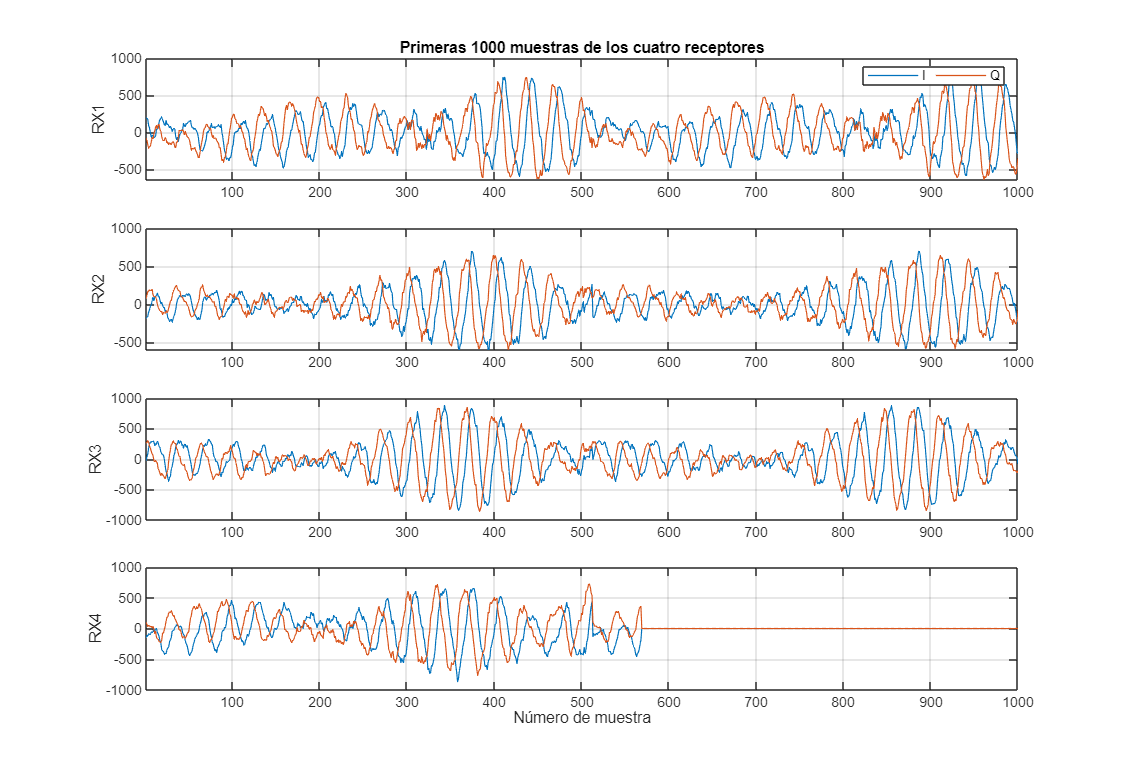

figure('Color','w','Position',[60 60 900 620]);
for r = 1:4
    x = X(:,:,1,r); x = x(1:1000);
    subplot(4,1,r);
    plot(real(x),'LineWidth',0.7); hold on; plot(imag(x),'LineWidth',0.7);
    grid on; xlim([1 1000]); ylabel(sprintf('RX%d',r));
    if r==1
        title('Primeras 1000 muestras de los cuatro receptores');
        legend({'I','Q'},'Location','northeast','Orientation','horizontal');
    end
end
xlabel('Número de muestra');

## 6. Un chirp completo en tiempo físico

Cada chirp son 512 muestras a 10 Msps, es decir $512 \times 0{,}1\ \mu s = 51{,}2\ \mu s$.

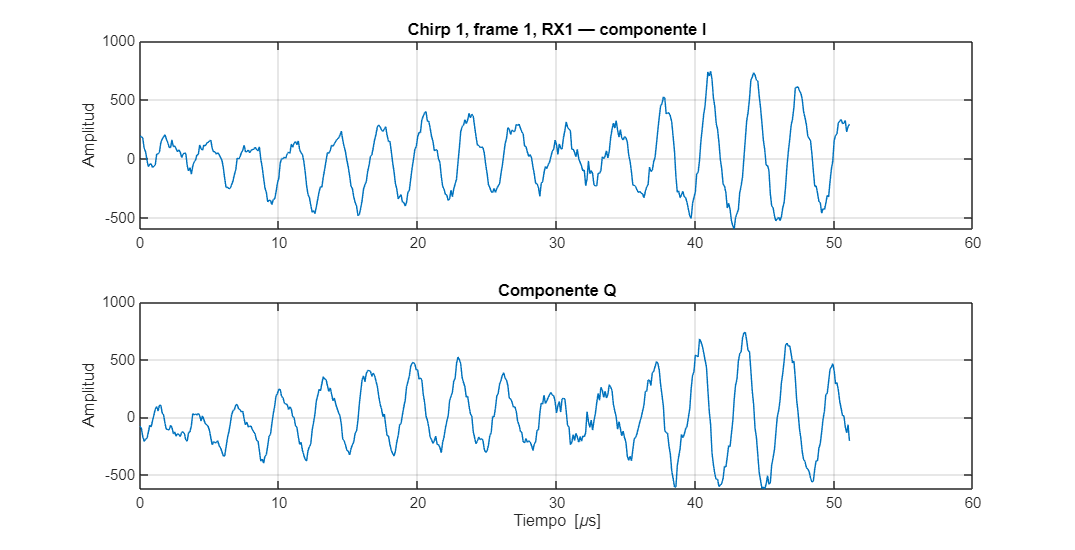

N  = P.N_muestras;
tc = (0:N-1)/P.Fs;
x1 = X(:,1,1,1);

figure('Color','w','Position',[60 60 860 440]);
subplot(2,1,1); plot(tc*1e6, real(x1)); grid on;
ylabel('Amplitud'); title('Chirp 1, frame 1, RX1 — componente I');
subplot(2,1,2); plot(tc*1e6, imag(x1)); grid on;
xlabel('Tiempo [\mus]'); ylabel('Amplitud'); title('Componente Q');

## 7. FFT de rango: de frecuencia de batido a distancia

La primera FFT se aplica sobre las 512 muestras de cada chirp (tiempo rápido). Antes se quita la componente continua, que corresponde al acoplamiento directo entre transmisor y receptor, y se aplica una ventana de Hann para reducir la fuga espectral del bloque finito.

En un radar FMCW la frecuencia de batido se traduce en distancia mediante:


$$R = \frac{c\,|f_b|}{2S}$$


con $S = 60{,}012$ MHz/$\mu$s la pendiente del chirp. Cada bin de la FFT equivale a $\Delta f = F_s/N = 19{,}53$ kHz, es decir **4,88 cm** de distancia.

Con el convenio I/Q de esta adquisición los blancos aparecen en las frecuencias de batido **negativas**, así que se conserva esa mitad del espectro.

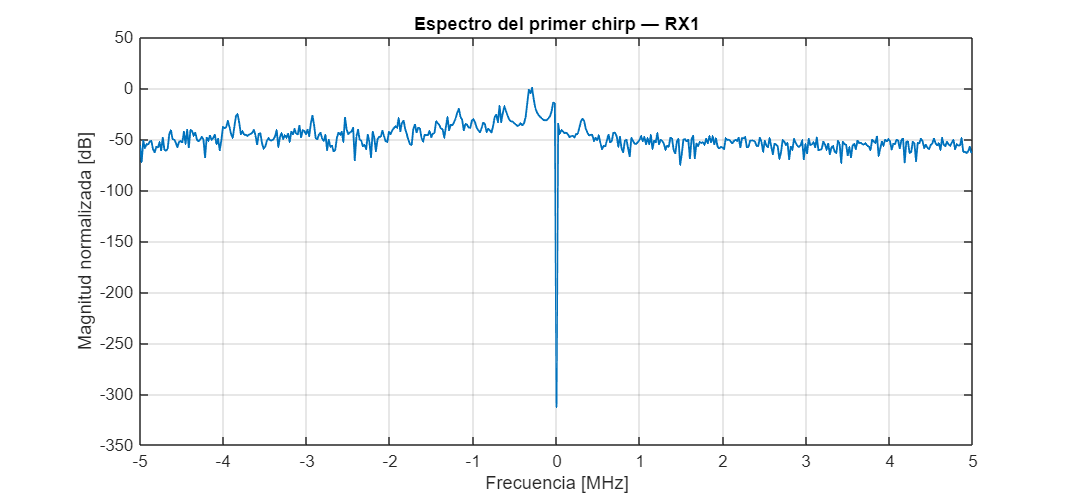

Xf = fftshift(fft(x1 - mean(x1)));
f  = (-N/2:N/2-1)'*(P.Fs/N);

figure('Color','w','Position',[60 60 860 400]);
plot(f/1e6, 20*log10(abs(Xf)/max(abs(Xf))+eps),'LineWidth',1.1); grid on;
xlabel('Frecuencia [MHz]'); ylabel('Magnitud normalizada [dB]');
title('Espectro del primer chirp — RX1');


[~,ip]  = max(abs(Xf));
f_beat  = f(ip);
fprintf('Frecuencia de batido dominante = %+.3f MHz  ->  R = %.2f m\n', ...
        f_beat/1e6, P.c*abs(f_beat)/(2*P.S));

Frecuencia de batido dominante = -0.293 MHz  ->  R = 0.73 m


## 8. Control de integridad de la adquisición

El DCA1000 envía las muestras por UDP y puede perder paquetes. Eso aparece como chirps enteros a cero. Conviene localizarlos antes de procesar, porque el análisis Doppler depende de la continuidad entre chirps.

El criterio que se usa es conservador: **no se eliminan chirps sueltos ni se interpolan datos**, se descartan frames completos.

V = verificar_integridad(X);

Chirps nulos: 10 de 51200, en 10 frames.
Tramo válido: frames 11-400 (390 frames, 97.5 % de la adquisición)


if ~isempty(V.tabla), disp(V.tabla); end

    Frame    Chirps_nulos
    _____    ____________

      1           1      
      2           1      
      3           1      
      4           1      
      5           1      
      6           1      
      7           1      
      8           1      
      9           1      
     10           1      



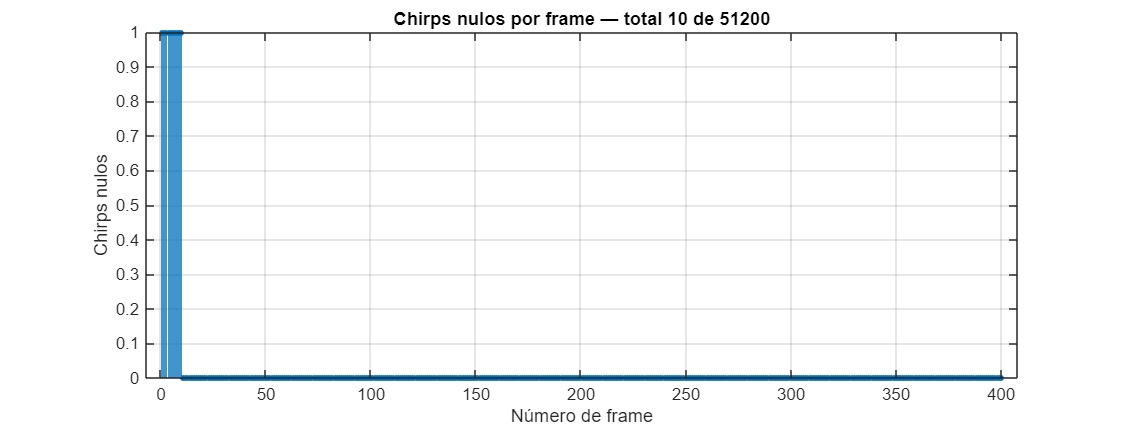


figure('Color','w','Position',[60 60 900 340]);
stem(1:size(X,3), V.nulos_por_frame, 'filled', 'MarkerSize', 3); grid on;
xlabel('Número de frame'); ylabel('Chirps nulos');
title(sprintf('Chirps nulos por frame — total %d de %d', ...
      V.total_nulos, size(X,2)*size(X,3)));

Los chirps nulos aparecen **solo en los primeros frames** y después desaparecen por completo. El compañero encontró exactamente el mismo patrón en la clase `Fast` (11 nulos repartidos en los frames 1 a 10). Que se repita indica que no es una pérdida aleatoria de paquetes, sino un **transitorio de arranque de la tarjeta de captura**.

## 9. Mapa rango-chirp y filtro MTI

Apilando los perfiles de rango de los 128 chirps de un frame se obtiene el mapa rango-chirp. Las bandas horizontales son reflexiones que no cambian de distancia: paredes, piso, estructuras.

Para atenuarlas se usa un MTI sencillo por sustracción de media. Para cada bin de distancia se promedia la respuesta compleja a lo largo de los 128 chirps y se resta:


$$x_{\mathrm{MTI}}[k] = x[k] - \frac{1}{128}\sum_{i=1}^{128} x[i]$$


Equivale a un filtro notch centrado en Doppler cero.

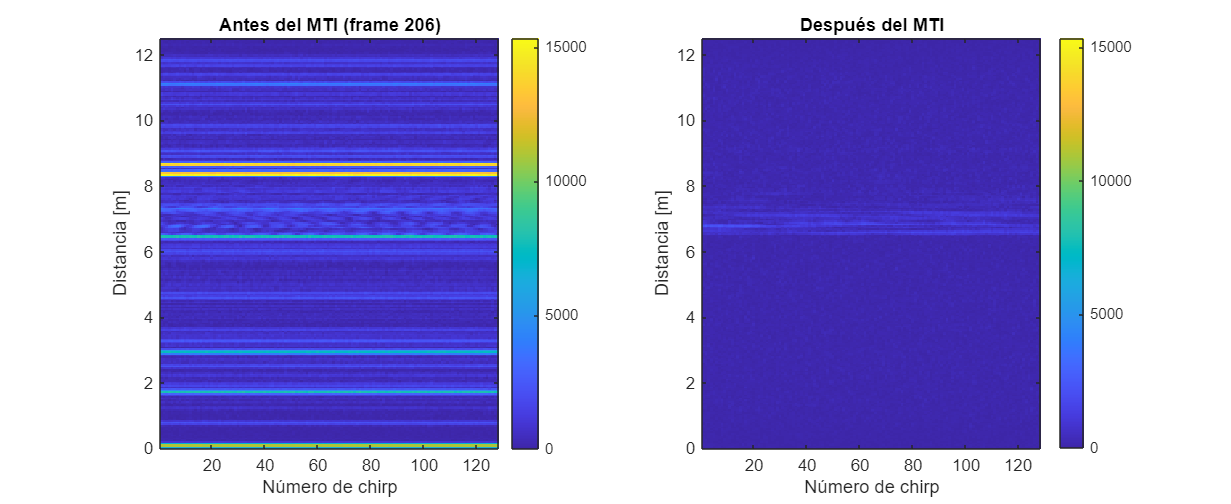

% Se elige un frame de la mitad del recorrido, cuando la persona ya está lejos
% del radar. En los primeros frames el sujeto está tan cerca que su eco domina
% el mapa y el MTI apenas tiene clutter fijo que restar.
m   = round(mean(V.rango_valido));
RP  = rango_fft(X(:,:,m,1), P);
RPm = mti(RP);

lim = max(abs(RP(:)));
figure('Color','w','Position',[60 60 1100 450]);
subplot(1,2,1);
imagesc(1:P.N_chirps, P.R_axis, abs(RP)); axis xy; colorbar; clim([0 lim]);
xlabel('Número de chirp'); ylabel('Distancia [m]');
title(sprintf('Antes del MTI (frame %d)', m));
subplot(1,2,2);
imagesc(1:P.N_chirps, P.R_axis, abs(RPm)); axis xy; colorbar; clim([0 lim]);
xlabel('Número de chirp'); ylabel('Distancia [m]');
title('Después del MTI');


fprintf('Reducción de energía total con el MTI: %.1f dB\n', ...
        10*log10(sum(abs(RP(:)).^2)/sum(abs(RPm(:)).^2)));

Reducción de energía total con el MTI: 19.4 dB


## 10. Mapa rango-Doppler: la segunda FFT

La primera FFT, sobre las 512 muestras de un chirp, da la distancia. La segunda FFT se aplica sobre la dimensión de los **128 chirps** de un frame y da la frecuencia Doppler, que se convierte a velocidad radial con:


$$v = \frac{\lambda f_D}{2}, \qquad \lambda = \frac{c}{f_c} = 3{,}9\
 \textrm{mm}$$


El intervalo entre chirps es $T_{chirp} = 100 + 60 = 160\ \mu s$, es decir 6250 chirps/s, lo que da un intervalo no ambiguo de $\pm 6{,}09$ m/s. Encaja con la suposición del artículo de que la velocidad del sujeto es menor que 6 m/s.

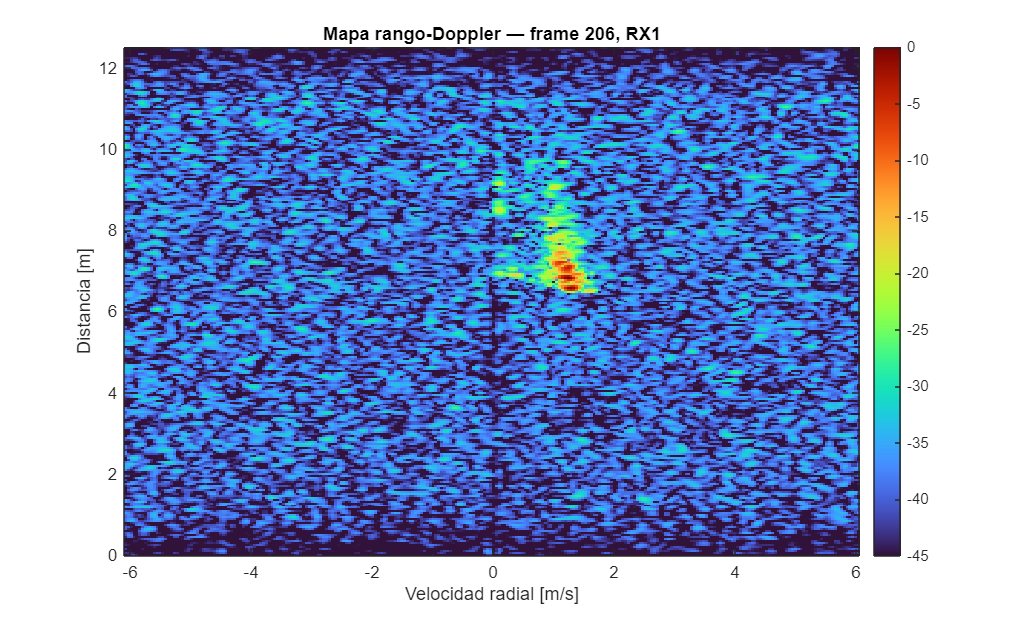

mc    = m;
RDm   = RPm;
D     = fftshift(fft(RDm .* hann(P.N_chirps,'periodic').', 256, 2), 2);
v256  = P.lambda*((-128:127)'*(P.PRF/256))/2;
D_dB  = 20*log10(abs(D)/max(abs(D(:)))+eps);

figure('Color','w','Position',[60 60 820 500]);
imagesc(v256, P.R_axis, D_dB); axis xy; colormap turbo; clim([-45 0]);
colorbar; xlabel('Velocidad radial [m/s]'); ylabel('Distancia [m]');
title(sprintf('Mapa rango-Doppler — frame %d, RX1', mc));


[pk,idx]   = max(abs(D(:)).^2);
[ir, idp]  = ind2sub(size(D), idx);
fprintf('Blanco detectado en R = %.2f m, v = %+.2f m/s\n', P.R_axis(ir), v256(idp));

Blanco detectado en R = 6.59 m, v = +1.28 m/s


fprintf('Contraste pico/mediana = %.1f dB\n', 10*log10(pk/median(abs(D(:)).^2)));

Contraste pico/mediana = 40.1 dB


## 11. Espectrograma micro-Doppler

Repitiendo el proceso en todos los frames se obtiene la evolución temporal del contenido Doppler, que es la representación tiempo-frecuencia que pide el proyecto.

Se calculan dos variantes:

- **Método por frame:** una sola FFT de los 128 chirps por frame. Da 25 columnas por segundo. Es el procesamiento clásico y el que usó el compañero.

- **STFT:** ventanas de 64 chirps con 75 % de solape **dentro** de cada frame. Da cuatro veces más resolución temporal. Es válido porque dentro del frame el muestreo lento sí es uniforme; entre frames hay un hueco de 19,52 ms que el eje de tiempo respeta.

Para colapsar la dimensión de distancia se toma, en cada celda Doppler, el **máximo** sobre los bins de distancia. Es mejor que sumarlos: integrar los ~215 bins del intervalo útil acumula el ruido de todos ellos mientras la persona ocupa solo unos pocos. Medido en este ensayo, el máximo da 65,5 dB de contraste frente a 53,1 dB de la suma.

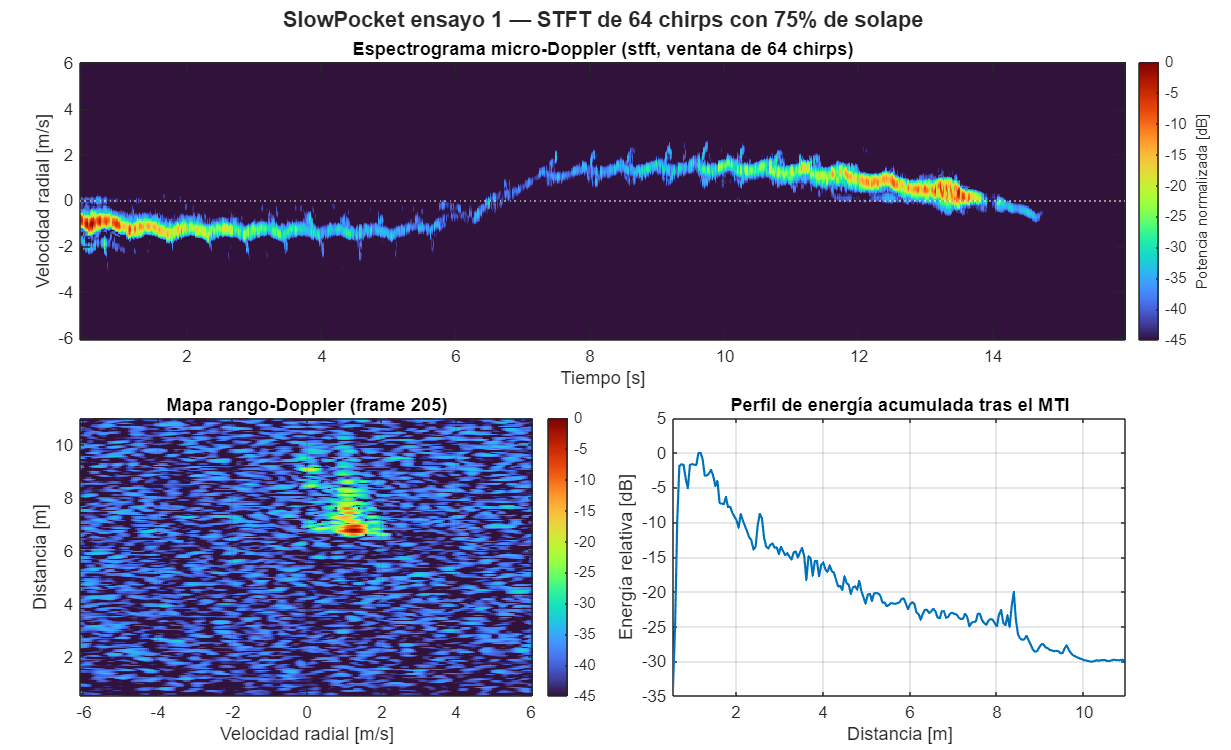

MD = microdoppler(X, P, V.rango_valido, 'stft');
graficar_microdoppler(MD, sprintf('SlowPocket ensayo %d — STFT de 64 chirps con 75%% de solape', ens));

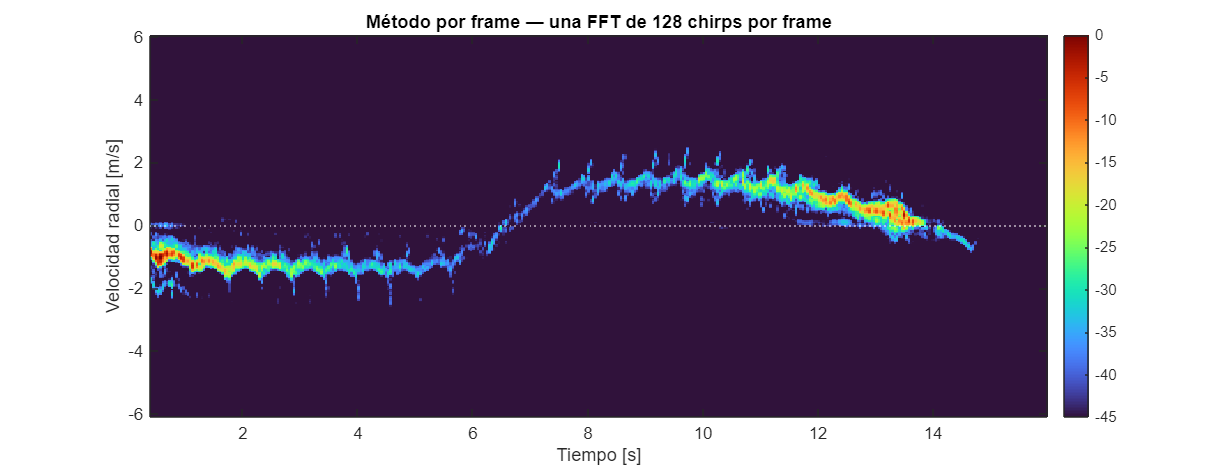

MDf = microdoppler(X, P, V.rango_valido, 'frame');
figure('Color','w','Position',[60 60 1050 400]);
imagesc(MDf.t, MDf.v, MDf.S_dB); axis xy; colormap turbo; clim([-45 0]);
colorbar; xlabel('Tiempo [s]'); ylabel('Velocidad radial [m/s]');
title('Método por frame — una FFT de 128 chirps por frame');
yline(0,'w:');

En el espectrograma se lee directamente la historia de la caminata: la traza del torso empieza en velocidades negativas (el sujeto se aleja del radar), cruza por cero cuando da la vuelta y pasa a velocidades positivas al regresar. Alrededor de esa línea principal hay un rizado periódico: es la contribución micro-Doppler de brazos y piernas, que se mueven a velocidades distintas de la del torso en cada paso.

clear X

## 12. Extracción de características Doppler

Sobre el espectrograma se calculan, columna a columna, los descriptores habituales del análisis de marcha:

- **centroide** — velocidad media ponderada por potencia.

- **envolventes** $v_{sup}$ y $v_{inf}$ — los percentiles 2 y 98 de la energía acumulada.

- **extensión** — $v_{sup}-v_{inf}$, el ancho total del micro-Doppler.

- **entropía espectral** — 0 para un tono puro, 1 para un espectro plano.

- **cadencia** — frecuencia de la oscilación de la extensión, en **pasos por segundo**. Ojo: la envolvente alcanza su máximo una vez por cada pierna, o sea dos veces por zancada, así que la cadencia es el doble de la frecuencia de zancada.

Dos detalles que resultaron imprescindibles con datos reales. Primero, hace falta un umbral doble (25 dB por debajo del pico **y** 15 dB por encima del piso de ruido): sin el segundo criterio el ruido, aunque sea el 1 % de la energía, está repartido por toda la banda y empuja las envolventes hasta $\pm v_{max}$. Segundo, las columnas en las que la persona está fuera del campo de visión no tienen señal alguna y hay que marcarlas como `NaN` en vez de asignarles una velocidad.

C = caracteristicas_doppler(MD);
disp(C.resumen);

    centroide_med    centroide_std    ancho_med    ancho_std    vtorso_med    vtorso_std    extension_med    extension_std    extension_max    v_max_pos    v_max_neg    frac_doppler_pos    entropia_med    cadencia_Hz    cadencia_pot    t_giro_s    frac_sin_senal
    _____________    _____________    _________    _________    __________    __________    _____________    _____________    _____________    _________    _________    ________________    ____________    ___________

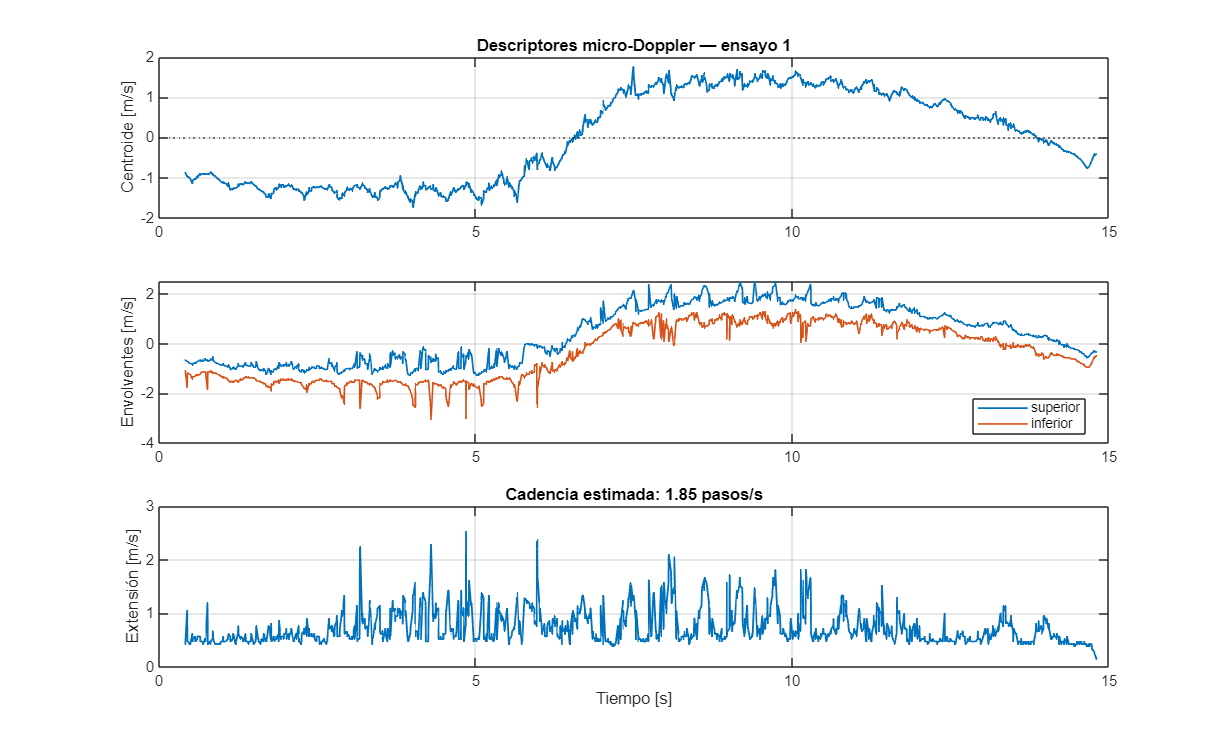


figure('Color','w','Position',[60 60 980 600]);
subplot(3,1,1);
plot(C.series.t, C.series.centroide,'LineWidth',1.1); grid on; yline(0,'k:');
ylabel('Centroide [m/s]'); title(sprintf('Descriptores micro-Doppler — ensayo %d', ens));
subplot(3,1,2);
plot(C.series.t, C.series.v_sup,'LineWidth',1); hold on;
plot(C.series.t, C.series.v_inf,'LineWidth',1); grid on;
ylabel('Envolventes [m/s]'); legend({'superior','inferior'},'Location','best');
subplot(3,1,3);
plot(C.series.t, C.series.extension,'LineWidth',1.1); grid on;
xlabel('Tiempo [s]'); ylabel('Extensión [m/s]');
title(sprintf('Cadencia estimada: %.2f pasos/s', C.resumen.cadencia_Hz));

## 13. Resultados del lote completo

El procesamiento de los 19 ensayos tardó 9,7 minutos (unos 30 s por ensayo, dominados por la lectura del `.mat`) y terminó sin errores. Aquí se cargan los descriptores ya calculados y guardados en `resultados\SlowPocket`.

Para reprocesar desde cero bastaría con:

pero no hace falta volver a leer los 8 GB para analizar los resultados.

S   = load(fullfile(SALIDA,'caracteristicas.mat'),'Res');
Res = S.Res;
Res = Res(~Res.Duplicado, :);          % se descarta la copia del ensayo 17
fprintf('Ensayos únicos analizados: %d\n\n', height(Res));

Ensayos únicos analizados: 18




disp(Res(:,{'Ensayo','chirps_nulos','pct_frames','centroide_std', ...
            'extension_med','cadencia_Hz','t_giro_s','entropia_med'}));

    Ensayo    chirps_nulos    pct_frames    centroide_std    extension_med    cadencia_Hz    t_giro_s    entropia_med
    ______    ____________    __________    _____________    _____________    ___________    ________    ____________

     "1"           10            97.5             1.12          0.73725         1.8494          6.6        0.42849   
     "2"            9           98.25          0.90806           0.6517         1.4709         9.32        0.44388   
     "3"            6           98.75          0.91879          0.60019         1.7456         8.48        0.43968   
     "4"           15           97.25           1.1547          0.77482           1.77         6.76        0.43213   
     "5"           

## 13.1 Integridad del conjunto

fprintf('Chirps nulos: %d de %d (%.3f %%)\n', ...
        sum(Res.chirps_nulos), height(Res)*P.N_chirps*P.N_frames, ...
        100*sum(Res.chirps_nulos)/(height(Res)*P.N_chirps*P.N_frames));

Chirps nulos: 174 de 921600 (0.019 %)


fprintf('Frames conservados: %.1f %% a %.1f %% (media %.1f %%)\n', ...
        min(Res.pct_frames), max(Res.pct_frames), mean(Res.pct_frames));

Frames conservados: 96.2 % a 100.0 % (media 98.0 %)


fprintf('Todos los nulos ocurren antes del frame %d\n', max(Res.primer_frame));

Todos los nulos ocurren antes del frame 16


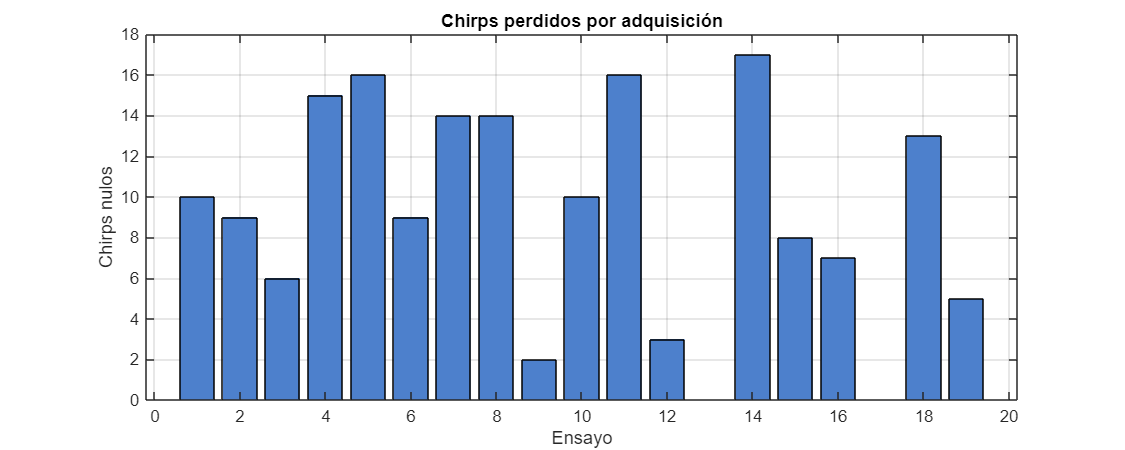


figure('Color','w','Position',[60 60 900 360]);
bar(str2double(Res.Ensayo), Res.chirps_nulos, 'FaceColor',[0.3 0.5 0.8]);
grid on; xlabel('Ensayo'); ylabel('Chirps nulos');
title('Chirps perdidos por adquisición');

## 13.2 Dispersión de los descriptores entre sujetos

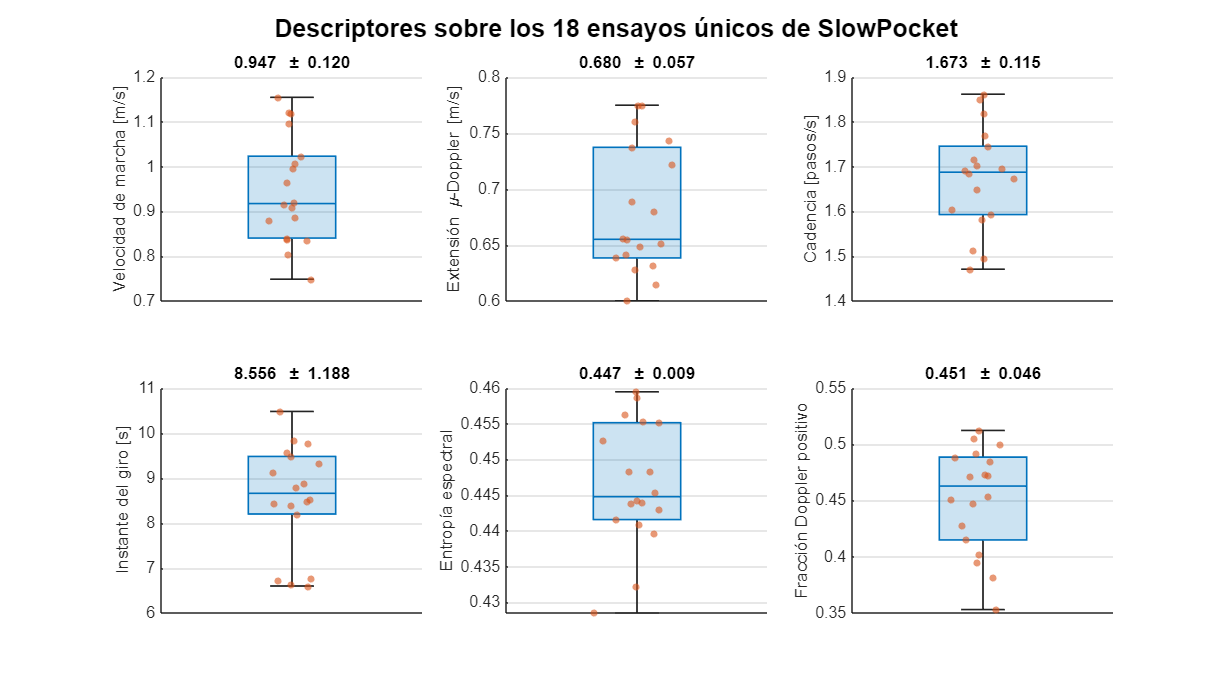

vars = {'centroide_std','extension_med','cadencia_Hz','t_giro_s', ...
        'entropia_med','frac_doppler_pos'};
etiq = {'Velocidad de marcha [m/s]','Extensión \mu-Doppler [m/s]', ...
        'Cadencia [pasos/s]','Instante del giro [s]', ...
        'Entropía espectral','Fracción Doppler positivo'};

figure('Color','w','Position',[50 50 1150 640]);
for k = 1:numel(vars)
    subplot(2,3,k);
    x = Res.(vars{k});
    boxchart(x, 'MarkerStyle','o'); hold on;
    scatter(1+0.08*randn(size(x)), x, 18, 'filled', 'MarkerFaceAlpha', 0.6);
    grid on; ylabel(etiq{k}); xticks([]);
    title(sprintf('%.3f \\pm %.3f', mean(x,'omitnan'), std(x,'omitnan')));
end
sgtitle('Descriptores sobre los 18 ensayos únicos de SlowPocket','FontWeight','bold');

## 13.3 Tabla resumen

resumen_lote = table( ...
    cellfun(@(v) mean(Res.(v),'omitnan'), vars)', ...
    cellfun(@(v) std(Res.(v),'omitnan'),  vars)', ...
    cellfun(@(v) min(Res.(v)), vars)', ...
    cellfun(@(v) max(Res.(v)), vars)', ...
    'VariableNames', {'Media','Desv','Min','Max'}, 'RowNames', vars);
disp(resumen_lote);

                         Media       Desv         Min        Max  
                        _______    _________    _______    _______

    centroide_std        0.9474      0.11998     0.7486     1.1547
    extension_med       0.68026     0.057093    0.60019    0.77482
    cadencia_Hz           1.673      0.11483     1.4709     1.8616
    t_giro_s             8.5556        1.188        6.6      10.48
    entropia_med        0.44651    0.0086558    0.42849    0.45946
    frac_doppler_pos    0.45142     0.046195    0.35306    0.51229



## 14. Conclusiones

**El procesamiento funciona y los números son físicamente coherentes.** Tres comprobaciones independientes lo respaldan:

- La velocidad de marcha estimada es de **0,95 ± 0,12 m/s**, que es el valor típico de una caminata lenta.

- La cadencia es de **1,67 ± 0,12 pasos/s**, equivalente a unos 100 pasos por minuto, también propio de marcha lenta.

- El cambio de sentido se detecta a los **8,6 ± 1,2 s** de los 16 s de la toma, es decir a mitad del recorrido, justo como describe el artículo. La fracción de tiempo con Doppler positivo es 0,45, muy cerca del 0,5 que cabría esperar si el sujeto se aleja la mitad del tiempo y vuelve la otra mitad.

**La calidad de la señal es alta:** el blanco se detecta con unos 44 dB de relación señal-ruido en el mapa rango-Doppler, el MTI reduce 15 dB la energía total (más de 25 dB en los reflectores fijos) y no hay recorte del convertidor.

**La dispersión entre sujetos es baja**, en torno al 2 % en entropía y extensión y al 7 % en cadencia, lo que sugiere que estos descriptores son estables y sirven para comparar entre clases.

**Qué queda pendiente.** Solo se dispone de 19 de los 57 ensayos de `SlowPocket`: faltan las partes 2 y 3 del repositorio. Una vez completadas, y repitiendo el mismo procesamiento sobre `Slow` y `Fast`, la comparación esperada es que la cadencia y la velocidad del torso separen `Fast` de `Slow`, mientras que la **extensión del micro-Doppler** separe `Slow` de `SlowPocket`: con las manos en los bolsillos desaparece la contribución del balanceo de los brazos, de modo que el espectrograma debería ser más estrecho.

Conviene además volver a pasar la detección de duplicados cuando estén los 57 ensayos juntos, y aprovechar la carpeta `background` del dataset para caracterizar el clutter del pasillo de forma independiente del MTI.

## Funciones locales

A partir de aquí están todas las funciones que usa el documento. Son las mismas que hay en la carpeta `codigo\` como archivos sueltos.

function P = cfg_radar()
%CFG_RADAR Parámetros del AWR1642 (Tabla 3 del artículo) y derivados.
P.S          = 60.012e12;   % pendiente del chirp [Hz/s]
P.t_idle     = 100e-6;      % tiempo muerto entre rampas [s]
P.t_adc_vs   = 6e-6;        % ADC valid start time [s]
P.Fs         = 10e6;        % muestreo del ADC [muestras/s]
P.t_ramp     = 60e-6;       % duración de la rampa [s]
P.N_muestras = 512;         % muestras útiles por chirp
P.N_frames   = 400;         % frames por adquisición
P.N_chirps   = 128;         % chirps por frame
P.T_period   = 40e-3;       % periodicidad de frame [s]
P.B_usado    = 3.6e9;       % ancho de banda barrido [Hz]
P.N_rx       = 4;
P.N_tx       = 1;
P.fc         = 77e9;        % portadora de referencia [Hz]
P.c          = 299792458;

P.T_adc   = P.N_muestras/P.Fs;
P.B_adc   = P.S*P.T_adc;
P.T_chirp = P.t_idle + P.t_ramp;
P.PRF     = 1/P.T_chirp;
P.t_frame = P.N_chirps*P.T_chirp;
P.fps     = 1/P.T_period;
P.duty    = P.t_frame/P.T_period;
P.T_total = P.N_frames*P.T_period;
P.N_total = P.N_muestras*P.N_chirps*P.N_frames;
P.lambda  = P.c/P.fc;
P.dR      = P.c*P.Fs/(2*P.S*P.N_muestras);
P.R_max   = P.dR*P.N_muestras/2;
P.R_axis  = (0:P.N_muestras/2)'*P.dR;
P.v_max   = P.lambda*P.PRF/4;
P.dv      = 2*P.v_max/P.N_chirps;
P.res_ang_deg = rad2deg(2/(P.N_tx*P.N_rx));
end

function tabla_parametros(P)
%TABLA_PARAMETROS Imprime la configuración y las magnitudes derivadas.
fprintf('Pendiente del chirp     S      = %.3f MHz/us\n', P.S/1e12);
fprintf('Ancho de banda          B      = %.2f GHz (muestreado %.3f GHz)\n', ...
        P.B_usado/1e9, P.B_adc/1e9);
fprintf('Muestreo del ADC        Fs     = %.0f Msps, %d muestras/chirp\n', ...
        P.Fs/1e6, P.N_muestras);
fprintf('Tiempo de chirp         Tchirp = %.0f us (idle %.0f + rampa %.0f)\n', ...
        P.T_chirp*1e6, P.t_idle*1e6, P.t_ramp*1e6);
fprintf('Repetición lenta        PRF    = %.0f chirps/s\n', P.PRF);
fprintf('Frame                          = %d chirps = %.2f ms activos\n', ...
        P.N_chirps, P.t_frame*1e3);
fprintf('Periodicidad de frame          = %.0f ms -> %.0f frames/s, %.1f %% de ciclo útil\n', ...
        P.T_period*1e3, P.fps, 100*P.duty);
fprintf('Adquisición                    = %d frames = %.0f s = %d muestras/RX\n', ...
        P.N_frames, P.T_total, P.N_total);
fprintf('Resolución de rango     dR     = %.2f cm, Rmax = %.2f m\n', P.dR*100, P.R_max);
fprintf('Resolución de velocidad dv     = %.3f m/s, vmax = +/- %.2f m/s\n', P.dv, P.v_max);
fprintf('Longitud de onda        lambda = %.2f mm\n', P.lambda*1e3);
fprintf('Array %d TX x %d RX -> %d elementos, resolución angular ~%.1f grados\n', ...
        P.N_tx, P.N_rx, P.N_tx*P.N_rx, P.res_ang_deg);
end

function T = localizar_adquisiciones(raiz)
%LOCALIZAR_ADQUISICIONES Inventario recursivo de los archivos adc_Data.mat.
d = dir(fullfile(raiz,'**','adc_Data.mat'));
assert(~isempty(d), 'No se encontró ningún adc_Data.mat bajo %s', raiz);

conocidas = ["Fast","Slow","SlowPocket","HidingBottle","Limping", ...
             "SlowWalk_SwingingHands","background"];
n = numel(d);
Clase = strings(n,1); Ensayo = strings(n,1); Ruta = strings(n,1); GB = zeros(n,1);
for i = 1:n
    Ruta(i) = string(fullfile(d(i).folder, d(i).name));
    GB(i)   = d(i).bytes/2^30;
    partes  = split(string(d(i).folder), filesep);
    partes  = partes(strlength(partes)>0);
    Ensayo(i) = partes(end);
    Clase(i)  = "desconocida";
    for k = numel(partes):-1:1
        j = find(strcmpi(partes(k), conocidas),1);
        if ~isempty(j), Clase(i) = conocidas(j); break; end
    end
end
T = table(Clase, Ensayo, Ruta, GB);
[~,ord] = sortrows([double(categorical(T.Clase)), str2double(T.Ensayo)], [1 2]);
T = T(ord,:);
end

function T = detectar_duplicados(T)
%DETECTAR_DUPLICADOS Marca adquisiciones con contenido idéntico.
%   La huella se calcula sobre bloques muestreados del archivo saltando los
%   128 bytes de cabecera, donde está la fecha de guardado. Así dos archivos
%   con los mismos datos y distinta fecha dan la misma huella.
n = height(T);
H = strings(n,1);
for i = 1:n, H(i) = huella(T.Ruta(i)); end
T.Huella = H;
[~,~,g]  = unique(H,'stable');
T.Duplicado = false(n,1);
for k = 1:max(g)
    idx = find(g==k);
    if numel(idx) > 1
        T.Duplicado(idx(2:end)) = true;
        fprintf(2,'Contenido idéntico (%d copias): %s\n', numel(idx), ...
                strjoin(T.Ensayo(idx)', ', '));
    end
end
if ~any(T.Duplicado)
    fprintf('Sin duplicados: las %d adquisiciones son distintas.\n', n);
else
    fprintf('Marcadas %d filas como duplicado. Fíltralas con T(~T.Duplicado,:).\n', ...
            sum(T.Duplicado));
end
end

function h = huella(ruta)
%HUELLA Firma SHA-256 de bloques muestreados del archivo, sin la cabecera.
d = dir(ruta);
cab = 128; util = d.bytes - cab;
fid = fopen(ruta,'r'); limpieza = onCleanup(@() fclose(fid)); %#ok<NASGU>
nb = 64; tam = 65536;
if util <= nb*tam, desp = cab; tam = util; nb = 1;
else,              desp = cab + round(linspace(0, util-tam, nb));
end
acc = uint8([]);
for k = 1:nb
    fseek(fid, desp(k), 'bof');
    acc = [acc; fread(fid, tam, '*uint8')]; %#ok<AGROW>
end
acc = [acc; typecast(uint64(d.bytes),'uint8')'];
motor = java.security.MessageDigest.getInstance('SHA-256');
motor.update(acc);
h = string(lower(reshape(dec2hex(typecast(motor.digest(),'uint8')).',1,[])));
end

function [X, info] = cargar_adc(ruta, P, rx)
%CARGAR_ADC Carga adc_Data.mat y lo reorganiza a muestras x chirps x frames x RX.
if nargin < 3 || isempty(rx), rx = 1:4; end
t0 = tic;
S  = load(ruta);
campos = fieldnames(S);
k = find(cellfun(@(f) istable(S.(f)), campos), 1);
assert(~isempty(k), 'No se encontró una tabla en %s', ruta);
var_nombre = campos{k};
Tb = S.(var_nombre); clear S
nombres = Tb.Properties.VariableNames;

col = zeros(1,numel(rx));
for i = 1:numel(rx)
    j = find(contains(nombres, sprintf('RX%d',rx(i)), 'IgnoreCase',true), 1);
    if isempty(j), j = rx(i); end
    col(i) = j;
end

Ns = P.N_muestras; Nc = P.N_chirps;
total = height(Tb);
Nf = floor(total/(Ns*Nc));
X  = complex(zeros(Ns, Nc, Nf, numel(rx)));
for i = 1:numel(rx)
    v = Tb.(nombres{col(i)});
    X(:,:,:,i) = reshape(v(1:Ns*Nc*Nf), Ns, Nc, Nf);
    clear v
end
clear Tb

info = struct('variable',var_nombre, 'columnas',{nombres}, 'rx',rx, ...
              'muestras_totales',total, 'n_frames',Nf, 'segundos',toc(t0));
end

function R = verificar_integridad(X, rx)
%VERIFICAR_INTEGRIDAD Localiza chirps nulos y el tramo de frames aprovechable.
if nargin < 2, rx = 1; end
maximos = squeeze(max(abs(X(:,:,:,rx)),[],1));     % [chirps x frames]
nulos   = sum(maximos == 0, 1);
limpios = find(nulos == 0);
assert(~isempty(limpios), 'Todos los frames tienen chirps nulos.');

saltos = [0, find(diff(limpios) > 1), numel(limpios)];
[~, b] = max(diff(saltos));
rango  = limpios(saltos(b)+1 : saltos(b+1));
afect  = find(nulos > 0);

R = struct('nulos_por_frame',nulos, 'total_nulos',sum(nulos), ...
           'frames_afectados',afect, 'primer_valido',rango(1), ...
           'ultimo_valido',rango(end), 'rango_valido',rango, ...
           'porcentaje',100*numel(rango)/size(X,3), ...
           'tabla', table(afect(:), nulos(afect)', ...
                          'VariableNames',{'Frame','Chirps_nulos'}));
fprintf(['Chirps nulos: %d de %d, en %d frames.\n' ...
         'Tramo válido: frames %d-%d (%d frames, %.1f %% de la adquisición)\n'], ...
        R.total_nulos, numel(maximos), numel(afect), ...
        R.primer_valido, R.ultimo_valido, numel(rango), R.porcentaje);
end

function RP = rango_fft(frame, P)
%RANGO_FFT Primera FFT: quita DC, aplica Hann y devuelve el semiespectro útil.
N = size(frame,1);
frame = frame - mean(frame,1);              % elimina el acoplamiento TX-RX
frame = frame .* hann(N,'periodic');        % reduce la fuga espectral
Xc = fftshift(fft(frame, [], 1), 1);
RP = Xc(N/2+1:-1:1, :);                     % de f=0 hacia -Fs/2
end

function Y = mti(RP)
%MTI Resta el promedio complejo entre chirps (notch en Doppler cero).
Y = RP - mean(RP, 2);
end

function MD = microdoppler(X, P, frames, metodo)
%MICRODOPPLER Espectrograma tiempo-velocidad de la adquisición completa.
%   metodo = 'stft'  -> ventanas de 64 chirps con 75 % de solape en el frame
%   metodo = 'frame' -> una FFT de los 128 chirps del frame
if nargin < 4, metodo = 'stft'; end
Ns = size(X,1); Nc = size(X,2);
NFFTd  = 256;
RangoM = [0.5 11];

R_full = P.R_axis(1:Ns/2+1);
bins   = find(R_full >= RangoM(1) & R_full <= RangoM(2));

if strcmpi(metodo,'frame'), Nw = Nc; hop = Nc;
else,                       Nw = 64; hop = 16;
end
inicios = 1 : hop : (Nc - Nw + 1);
nv      = numel(inicios);
wD      = hann(Nw,'periodic');

fD = (-NFFTd/2 : NFFTd/2-1)'*(P.PRF/NFFTd);
v  = P.lambda*fD/2;

nF   = numel(frames);
Ppow = zeros(NFFTd, nF*nv);
t    = zeros(1, nF*nv);
cfrm = zeros(1, nF*nv);
perfil = zeros(numel(bins),1);
RD = []; RD_frame = frames(max(1,round(nF/2)));

col = 0;
for ii = 1:nF
    m  = frames(ii);
    RP = mti(rango_fft(double(X(:,:,m,1)), P));
    RP = RP(bins,:);
    for w = 1:nv
        seg = RP(:, inicios(w):inicios(w)+Nw-1) .* wD.';
        Pd  = abs(fftshift(fft(seg, NFFTd, 2), 2)).^2;
        Ppow(:, col+w) = max(Pd, [], 1).';     % máximo sobre los bins de rango
        if w == 1, perfil = perfil + sum(Pd,2); end
        if m == RD_frame && w == 1, RD = sqrt(Pd); end
    end
    centros = inicios + Nw/2 - 0.5;
    t(col+(1:nv))    = (m-1)*P.T_period + (centros-1)*P.T_chirp;
    cfrm(col+(1:nv)) = m;
    col = col + nv;
end

S = sqrt(Ppow);
MD = struct('S',S, 'S_dB',20*log10(S/max(S(:))+eps), 'v',v, 'fD',fD, ...
            't',t, 'frames',cfrm, 'R_axis',R_full(bins), 'RD',RD, ...
            'RD_frame',RD_frame, 'perfil_rango',perfil, 'metodo',metodo, ...
            'Ventana',Nw, 'P',P);
end

function graficar_microdoppler(MD, titulo)
%GRAFICAR_MICRODOPPLER Espectrograma, mapa rango-Doppler y perfil de energía.
fig = figure('Color','w','Position',[50 50 1150 700]);
tl  = tiledlayout(fig, 2, 2, 'TileSpacing','compact','Padding','compact');
title(tl, titulo, 'Interpreter','none', 'FontWeight','bold');

ax1 = nexttile(tl, 1, [1 2]);
imagesc(ax1, MD.t, MD.v, MD.S_dB); axis(ax1,'xy');
colormap(ax1, turbo); clim(ax1, [-45 0]);
cb = colorbar(ax1); cb.Label.String = 'Potencia normalizada [dB]';
xlabel(ax1,'Tiempo [s]'); ylabel(ax1,'Velocidad radial [m/s]');
title(ax1, sprintf('Espectrograma micro-Doppler (%s, ventana de %d chirps)', ...
      MD.metodo, MD.Ventana));
yline(ax1, 0, 'w:'); grid(ax1,'on');

ax2 = nexttile(tl, 3);
RD_dB = 20*log10(MD.RD/max(MD.RD(:))+eps);
imagesc(ax2, MD.v, MD.R_axis, RD_dB); axis(ax2,'xy');
colormap(ax2, turbo); clim(ax2,[-45 0]); colorbar(ax2);
xlabel(ax2,'Velocidad radial [m/s]'); ylabel(ax2,'Distancia [m]');
title(ax2, sprintf('Mapa rango-Doppler (frame %d)', MD.RD_frame)); grid(ax2,'on');

ax3 = nexttile(tl, 4);
pr = MD.perfil_rango/max(MD.perfil_rango+eps);
plot(ax3, MD.R_axis, 10*log10(pr+eps), 'LineWidth',1.3); grid(ax3,'on');
xlabel(ax3,'Distancia [m]'); ylabel(ax3,'Energía relativa [dB]');
title(ax3,'Perfil de energía acumulada tras el MTI');
xlim(ax3, [MD.R_axis(1) MD.R_axis(end)]);
end

function C = caracteristicas_doppler(MD)
%CARACTERISTICAS_DOPPLER Descriptores del espectrograma micro-Doppler.
UmbralDB = -25;    % dB por debajo del pico de cada columna
SNRenv   = 15;     % dB por encima del piso de ruido
MinBins  = 3;      % bins contiguos mínimos para considerar que hay señal
FracEnv  = 0.02;   % cola de energía que se recorta en cada envolvente
Banda    = [1.2 2.8];   % pasos/s fisiológicamente posibles

v  = MD.v(:);
Pw = double(MD.S).^2;
nv = numel(v);

% Umbral doble: relativo al pico y relativo al ruido. El segundo es
% imprescindible, porque el ruido está repartido por toda la banda.
pico   = max(Pw,[],1);
ruido  = median(Pw,1);
umbral = max(pico*10^(UmbralDB/10), ruido*10^(SNRenv/10));
Pc = Pw; Pc(Pc < umbral) = 0;

% Se exige una racha de MinBins contiguos: el máximo sobre los bins de rango
% genera picos de ruido aislados por toda la banda.
mask    = Pc > 0;
inicios = movsum(mask, [0 MinBins-1], 1) == MinBins;
mask    = movmax(double(inicios), [MinBins-1 0], 1) > 0;
Pc(~mask) = 0;

E = sum(Pc,1); E(E==0) = eps;
centroide = (v.'*Pc)./E;
ancho     = sqrt(max(((v.^2).'*Pc)./E - centroide.^2, 0));
[~,imax]  = max(Pc,[],1);
v_torso   = v(imax).';

% Envolventes por percentil de energía acumulada, no por el bin más externo.
Pn    = Pc ./ E;
acum  = cumsum(Pn,1);
inf_i = min(sum(acum < FracEnv,   1) + 1, nv);
sup_i = min(sum(acum < 1-FracEnv, 1) + 1, nv);
v_inf = v(inf_i).';  v_sup = v(sup_i).';
extension = v_sup - v_inf;

% Columnas sin señal (persona fuera del campo de visión): energía nula, el
% percentil devolvería el último bin. Se marcan como NaN.
sin_senal = ~any(Pc > 0, 1);
v_inf(sin_senal)=NaN; v_sup(sin_senal)=NaN; extension(sin_senal)=NaN;
centroide(sin_senal)=NaN; ancho(sin_senal)=NaN; v_torso(sin_senal)=NaN;

Pe = Pc./E; Pe(Pe<=0) = eps;
entropia = -sum(Pe.*log(Pe),1)/log(nv);

series = table(MD.t(:), MD.frames(:), centroide(:), ancho(:), v_torso(:), ...
               v_sup(:), v_inf(:), extension(:), E(:), entropia(:), ...
    'VariableNames',{'t','frame','centroide','ancho','v_torso', ...
                     'v_sup','v_inf','extension','energia','entropia'});

% Cadencia: la serie por frame sí es uniforme (25 Hz), a diferencia del eje
% completo de la STFT, que tiene huecos entre frames.
ext_f = accumarray(findgroups(MD.frames(:)), rellenar(extension)', [], @mean);
cen_f = accumarray(findgroups(MD.frames(:)), rellenar(centroide)', [], @mean);
frames_u = unique(MD.frames);

fps  = MD.P.fps;
x    = ext_f - mean(ext_f);
Nfft = 2^nextpow2(8*numel(x));
Xf   = abs(fft(x.*hann(numel(x)), Nfft)).^2;
f    = (0:Nfft-1).'*fps/Nfft;
banda = f >= Banda(1) & f <= Banda(2) & f < fps/2;
% La banda evita que el estimador enganche el segundo armónico: las dos
% piernas contribuyen de forma muy simétrica a la envolvente.
if any(banda)
    [pk,ipk] = max(Xf.*banda);
    cadencia = f(ipk);  pot_rel = pk/sum(Xf(f < fps/2));
else
    cadencia = NaN; pot_rel = NaN;
end

% Giro: mínimo de |centroide| suavizado en el 20-80 % central del registro.
cen_s = movmean(cen_f, max(3, round(fps)));
nfr = numel(cen_s); lo = max(1,round(0.2*nfr)); hi = min(nfr,round(0.8*nfr));
if hi > lo
    [~,ic] = min(abs(cen_s(lo:hi)));
    t_giro = (frames_u(lo+ic-1)-1)/fps;
else
    t_giro = NaN;
end

val = isfinite(centroide);
resumen = table( ...
    mean(centroide,'omitnan'), std(centroide,'omitnan'), ...
    mean(ancho,'omitnan'),     std(ancho,'omitnan'), ...
    mean(v_torso,'omitnan'),   std(v_torso,'omitnan'), ...
    mean(extension,'omitnan'), std(extension,'omitnan'), pct(extension,95), ...
    pct(v_sup,95), pct(v_inf,5), sum(centroide>0)/max(sum(val),1), ...
    mean(entropia,'omitnan'), cadencia, pot_rel, t_giro, mean(~val), ...
    'VariableNames',{'centroide_med','centroide_std','ancho_med','ancho_std', ...
                     'vtorso_med','vtorso_std','extension_med','extension_std', ...
                     'extension_max','v_max_pos','v_max_neg','frac_doppler_pos', ...
                     'entropia_med','cadencia_Hz','cadencia_pot','t_giro_s', ...
                     'frac_sin_senal'});

C = struct('series',series, 'resumen',resumen, ...
           'extension_frame',ext_f, 'centroide_frame',cen_f, 'frames',frames_u(:));
end

function y = pct(x, p)
%PCT Percentil p por interpolación lineal, sin Statistics Toolbox.
x = sort(x(isfinite(x))); n = numel(x);
if n == 0, y = NaN; return; end
if n == 1, y = x;   return; end
pos = 1 + (p/100)*(n-1); lo = floor(pos); hi = ceil(pos);
y = x(lo) + (pos-lo)*(x(hi)-x(lo));
end

function y = rellenar(x)
%RELLENAR Interpola los NaN de una serie para poder aplicarle la FFT.
y = x(:).'; ok = isfinite(y);
if all(ok) || ~any(ok), return; end
idx = 1:numel(y);
y(~ok) = interp1(idx(ok), y(ok), idx(~ok), 'linear', 'extrap');
end